# **Error Space Approach**

**NEED TUNING ON ALL**

**MOST IMPORTANT IS 0.5 WHICH IS NEEDED IN LAB**

load('parameters.mat');
% Track sinusoid reference of specified frequency and be robust against
% constant disturbance.



Controller for Trs=0.15


%%% Reference frequencies
ssError.amp = 0;                    % Choose sinusoide amplitude
ssError.Trs = 0.15;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi./ssError.Trs;    % T[s] -> w[rad/s]

%%% Signal model
% By IMP: char. Equation: (s^2 + wr^2) * s
ssError.denomH = [1 0 ssError.wrs^2 0]; % denominator of compensator H(s)
ssError.Ar = [0 1 0; 0 0 1; 0 -ssError.wrs^2 0]; % maybe change to alternate for better condition number

%%% Error Space Model
ssError.Az = [ssError.Ar, [zeros(2,2);ssP.C]; zeros(2,3), ssP.A];
ssError.Bz = [zeros(3,1); ssP.B]; % Note: Reachable as ssP is reachable and has no zeros (see handout)

%%% Place Poles (TENTIATIVE VALUES FROM ASSIGNMENT -- TUNE!)
perf.wnmin = perf.sigmamin/perf.d; % Natural frequency from minimal performance criteria

% Matlab doesn't recognize that the poles below are conjugate, explicitly
% set the values.
% ssError.poles = perf.wnmin*[exp(1i*(-1+1/4)*pi) exp(1i*(-1-1/4)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1]; 

ssError.poles = 1.8*perf.wnmin*[-0.7071-0.7071i -0.7071+0.7071i -0.8660-0.5000i  -0.8660+0.5000i -1.0000];
ssError.Kz = place(ssError.Az, ssError.Bz, ssError.poles);
ssError.Kz % First gain on order of 10^5, something is wrong.

ans = 1.0e+06 *

    5.3271    0.0679    0.0081    0.0002    0.0000


%%% Translate back to real system
ssError.nomH = flip(ssError.Kz(1:3)); % nominator of compensator H(s), flip to get correct order for tf
ssError.K = ssError.Kz(4:5); % State-Feedback gain on original system



SIMULATIONS

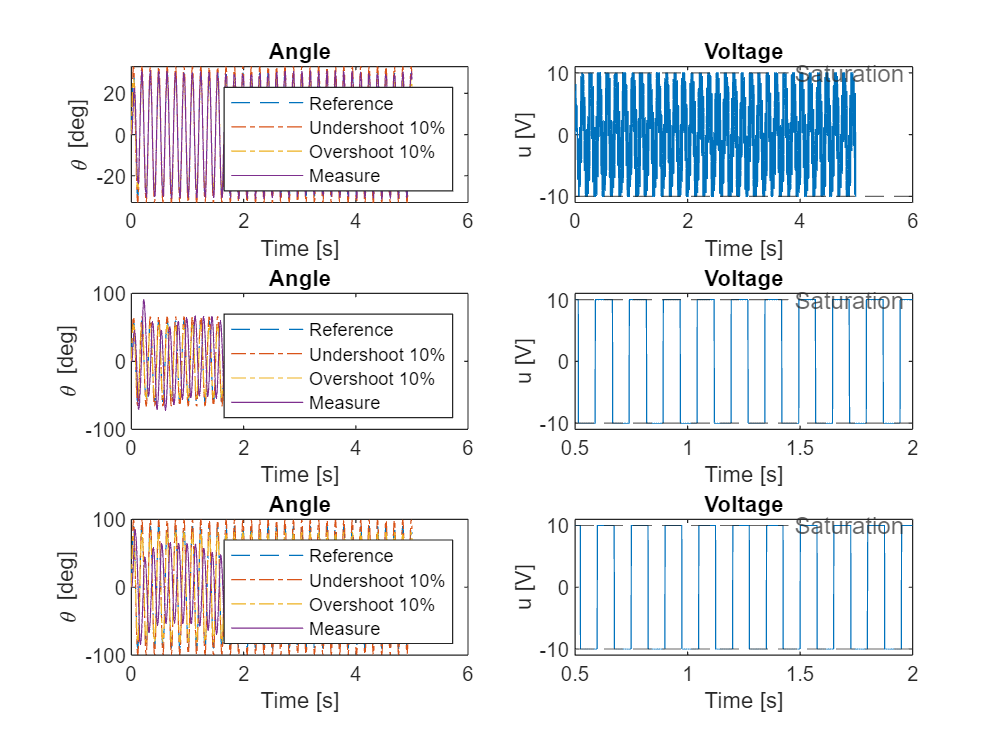

ssError.amp = 30;
ssError_simul.Tr1.amp30 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssError_simul.Tr1.amp60 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssError_simul.Tr1.amp90 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssError_simul.Tr1.amp30.thref.time, ssError_simul.Tr1.amp30.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr1.amp30.thref.time, ssError_simul.Tr1.amp30.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr1.amp30.thref.time, ssError_simul.Tr1.amp30.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr1.amp30.thl_meas.time, ssError_simul.Tr1.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssError_simul.Tr1.amp30.u.time, ssError_simul.Tr1.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssError_simul.Tr1.amp60.thref.time, ssError_simul.Tr1.amp60.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr1.amp60.thref.time, ssError_simul.Tr1.amp60.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr1.amp60.thref.time, ssError_simul.Tr1.amp60.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr1.amp60.thl_meas.time, ssError_simul.Tr1.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssError_simul.Tr1.amp60.u.time, ssError_simul.Tr1.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(ssError_simul.Tr1.amp90.thref.time, ssError_simul.Tr1.amp90.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr1.amp90.thref.time, ssError_simul.Tr1.amp90.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr1.amp90.thref.time, ssError_simul.Tr1.amp90.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr1.amp90.thl_meas.time, ssError_simul.Tr1.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssError_simul.Tr1.amp90.u.time, ssError_simul.Tr1.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

Controller for Trs=0.25


%%% Reference frequencies
ssError.amp = 0;                    % Choose sinusoide amplitude
ssError.Trs = 0.25;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi./ssError.Trs;    % T[s] -> w[rad/s]

%%% Signal model
% By IMP: char. Equation: (s^2 + wr^2) * s
ssError.denomH = [1 0 ssError.wrs^2 0]; % denominator of compensator H(s)
ssError.Ar = [0 1 0; 0 0 1; 0 -ssError.wrs^2 0]; % maybe change to alternate for better condition number

%%% Error Space Model
ssError.Az = [ssError.Ar, [zeros(2,2);ssP.C]; zeros(2,3), ssP.A];
ssError.Bz = [zeros(3,1); ssP.B]; % Note: Reachable as ssP is reachable and has no zeros (see handout)

%%% Place Poles (TENTIATIVE VALUES FROM ASSIGNMENT -- TUNE!)
perf.wnmin = perf.sigmamin/perf.d; % Natural frequency from minimal performance criteria

% Matlab doesn't recognize that the poles below are conjugate, explicitly
% set the values.
% ssError.poles = perf.wnmin*[exp(1i*(-1+1/4)*pi) exp(1i*(-1-1/4)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1]; 

ssError.poles = 1.8*perf.wnmin*[-0.7071-0.7071i -0.7071+0.7071i -0.8660-0.5000i  -0.8660+0.5000i -1.0000];
ssError.Kz = place(ssError.Az, ssError.Bz, ssError.poles);
ssError.Kz % First gain on order of 10^5, something is wrong.

ans = 1.0e+06 *

    5.3271    0.2521    0.0099    0.0002    0.0000


%%% Translate back to real system
ssError.nomH = flip(ssError.Kz(1:3)); % nominator of compensator H(s), flip to get correct order for tf
ssError.K = ssError.Kz(4:5); % State-Feedback gain on original system


SIMULATIONS

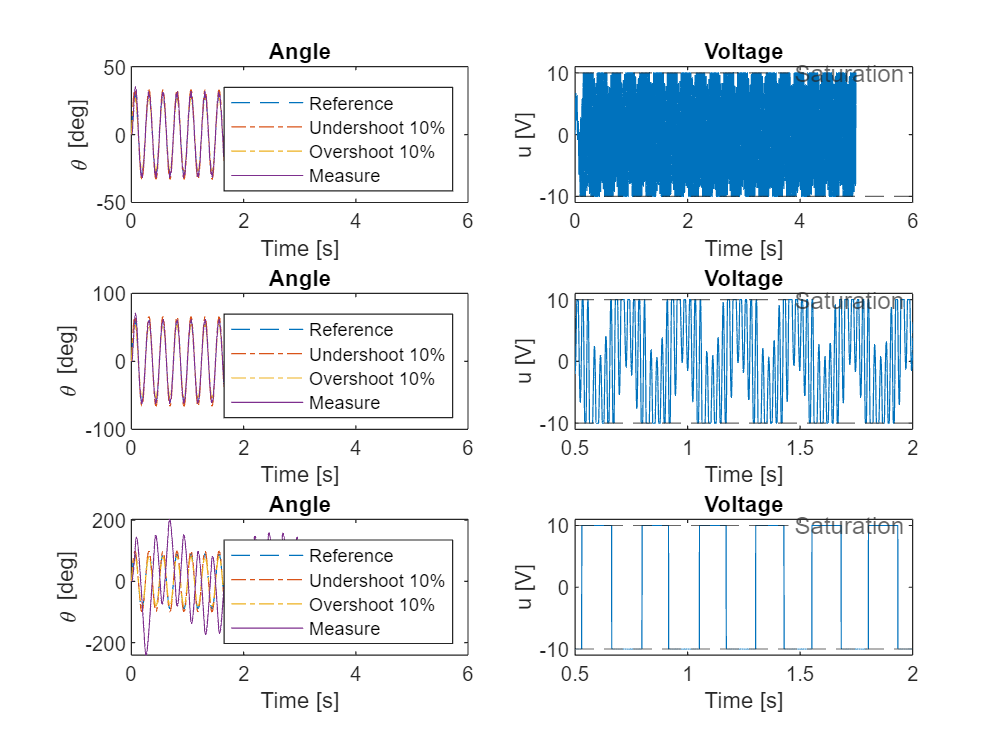

ssError.amp = 30;
ssError_simul.Tr2.amp30 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssError_simul.Tr2.amp60 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssError_simul.Tr2.amp90 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssError_simul.Tr2.amp30.thref.time, ssError_simul.Tr2.amp30.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr2.amp30.thref.time, ssError_simul.Tr2.amp30.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr2.amp30.thref.time, ssError_simul.Tr2.amp30.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr2.amp30.thl_meas.time, ssError_simul.Tr2.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssError_simul.Tr2.amp30.u.time, ssError_simul.Tr2.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssError_simul.Tr2.amp60.thref.time, ssError_simul.Tr2.amp60.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr2.amp60.thref.time, ssError_simul.Tr2.amp60.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr2.amp60.thref.time, ssError_simul.Tr2.amp60.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr2.amp60.thl_meas.time, ssError_simul.Tr2.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssError_simul.Tr2.amp60.u.time, ssError_simul.Tr2.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(ssError_simul.Tr2.amp90.thref.time, ssError_simul.Tr2.amp90.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr2.amp90.thref.time, ssError_simul.Tr2.amp90.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr2.amp90.thref.time, ssError_simul.Tr2.amp90.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr2.amp90.thl_meas.time, ssError_simul.Tr2.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssError_simul.Tr2.amp90.u.time, ssError_simul.Tr2.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

Controller for Trs=0.5 

## TUNED VALUES NEEDS TO BE CHANGED ALSO IN AUTOMATED_SIMULATION


%%% Reference frequencies
ssError.amp = 0;                    % Choose sinusoide amplitude
ssError.Trs = 0.5;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi./ssError.Trs;    % T[s] -> w[rad/s]

%%% Signal model
% By IMP: char. Equation: (s^2 + wr^2) * s
ssError.denomH = [1 0 ssError.wrs^2 0]; % denominator of compensator H(s)
ssError.Ar = [0 1 0; 0 0 1; 0 -ssError.wrs^2 0]; % maybe change to alternate for better condition number

%%% Error Space Model
ssError.Az = [ssError.Ar, [zeros(2,2);ssP.C]; zeros(2,3), ssP.A];
ssError.Bz = [zeros(3,1); ssP.B]; % Note: Reachable as ssP is reachable and has no zeros (see handout)

%%% Place Poles (TENTIATIVE VALUES FROM ASSIGNMENT -- TUNE!)
perf.wnmin = perf.sigmamin/perf.d; % Natural frequency from minimal performance criteria

% Matlab doesn't recognize that the poles below are conjugate, explicitly
% set the values.
% ssError.poles = perf.wnmin*[exp(1i*(-1+1/4)*pi) exp(1i*(-1-1/4)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1]; 

ssError.poles = 1.8*perf.wnmin*[-0.7071-0.7071i -0.7071+0.7071i -0.8660-0.5000i  -0.8660+0.5000i -1.0000];
ssError.Kz = place(ssError.Az, ssError.Bz, ssError.poles);
ssError.Kz % First gain on order of 10^5, something is wrong.

ans = 1.0e+06 *

    5.3271    0.3346    0.0107    0.0002    0.0000


%%% Translate back to real system
ssError.nomH = flip(ssError.Kz(1:3)); % nominator of compensator H(s), flip to get correct order for tf
ssError.K = ssError.Kz(4:5); % State-Feedback gain on original system


SIMULATIONS

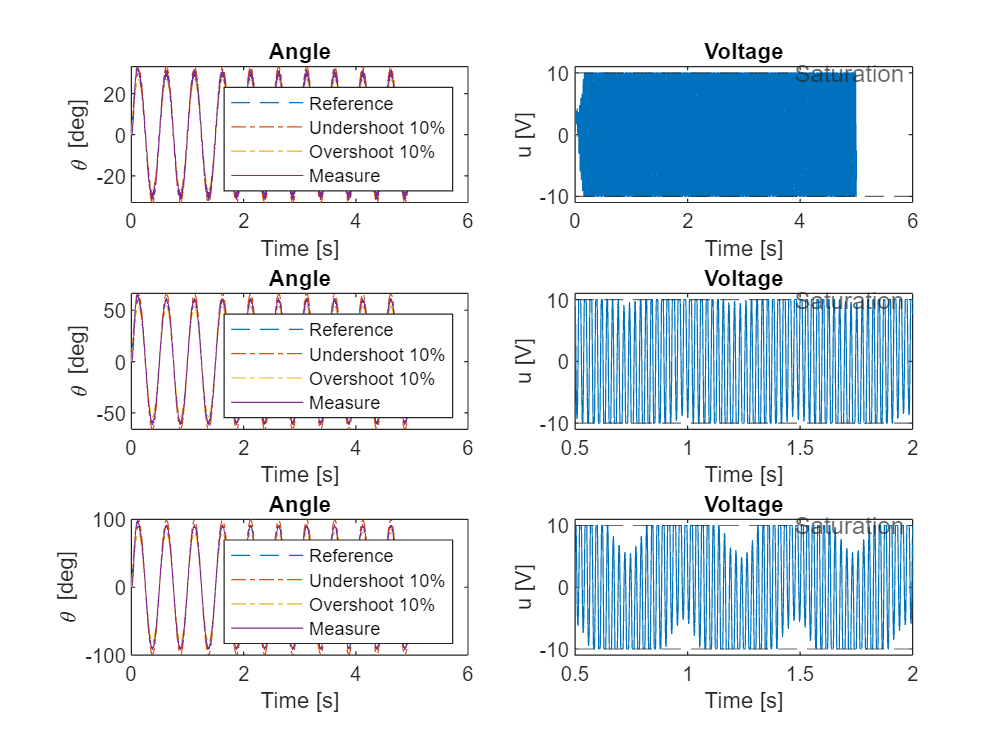

ssError.amp = 30;
ssError_simul.Tr3.amp30 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssError_simul.Tr3.amp60 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssError_simul.Tr3.amp90 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssError_simul.Tr3.amp30.thref.time, ssError_simul.Tr3.amp30.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr3.amp30.thref.time, ssError_simul.Tr3.amp30.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr3.amp30.thref.time, ssError_simul.Tr3.amp30.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr3.amp30.thl_meas.time, ssError_simul.Tr3.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssError_simul.Tr3.amp30.u.time, ssError_simul.Tr3.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssError_simul.Tr3.amp60.thref.time, ssError_simul.Tr3.amp60.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr3.amp60.thref.time, ssError_simul.Tr3.amp60.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr3.amp60.thref.time, ssError_simul.Tr3.amp60.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr3.amp60.thl_meas.time, ssError_simul.Tr3.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssError_simul.Tr3.amp60.u.time, ssError_simul.Tr3.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(ssError_simul.Tr3.amp90.thref.time, ssError_simul.Tr3.amp90.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr3.amp90.thref.time, ssError_simul.Tr3.amp90.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr3.amp90.thref.time, ssError_simul.Tr3.amp90.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr3.amp90.thl_meas.time, ssError_simul.Tr3.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssError_simul.Tr3.amp90.u.time, ssError_simul.Tr3.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

Controller for Trs=1


%%% Reference frequencies
ssError.amp = 0;                    % Choose sinusoide amplitude
ssError.Trs = 1;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi./ssError.Trs;    % T[s] -> w[rad/s]

%%% Signal model
% By IMP: char. Equation: (s^2 + wr^2) * s
ssError.denomH = [1 0 ssError.wrs^2 0]; % denominator of compensator H(s)
ssError.Ar = [0 1 0; 0 0 1; 0 -ssError.wrs^2 0]; % maybe change to alternate for better condition number

%%% Error Space Model
ssError.Az = [ssError.Ar, [zeros(2,2);ssP.C]; zeros(2,3), ssP.A];
ssError.Bz = [zeros(3,1); ssP.B]; % Note: Reachable as ssP is reachable and has no zeros (see handout)

%%% Place Poles (TENTIATIVE VALUES FROM ASSIGNMENT -- TUNE!)
perf.wnmin = perf.sigmamin/perf.d; % Natural frequency from minimal performance criteria

% Matlab doesn't recognize that the poles below are conjugate, explicitly
% set the values.
% ssError.poles = perf.wnmin*[exp(1i*(-1+1/4)*pi) exp(1i*(-1-1/4)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1]; 

ssError.poles = 1.8*perf.wnmin*[-0.7071-0.7071i -0.7071+0.7071i -0.8660-0.5000i  -0.8660+0.5000i -1.0000];
ssError.Kz = place(ssError.Az, ssError.Bz, ssError.poles);
ssError.Kz % First gain on order of 10^5, something is wrong.

ans = 1.0e+06 *

    5.3271    0.3556    0.0108    0.0002    0.0000


%%% Translate back to real system
ssError.nomH = flip(ssError.Kz(1:3)); % nominator of compensator H(s), flip to get correct order for tf
ssError.K = ssError.Kz(4:5); % State-Feedback gain on original system


SIMULATIONS

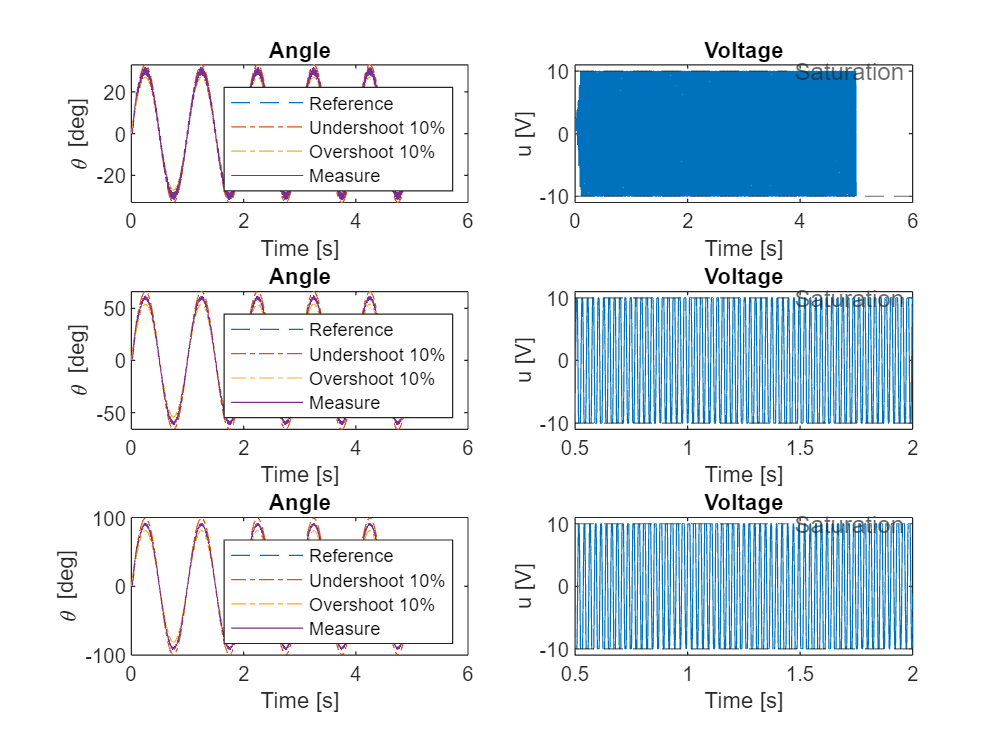

ssError.amp = 30;
ssError_simul.Tr4.amp30 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
ssError_simul.Tr4.amp60 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
ssError_simul.Tr4.amp90 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(ssError_simul.Tr4.amp30.thref.time, ssError_simul.Tr4.amp30.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr4.amp30.thref.time, ssError_simul.Tr4.amp30.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr4.amp30.thref.time, ssError_simul.Tr4.amp30.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr4.amp30.thl_meas.time, ssError_simul.Tr4.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(ssError_simul.Tr4.amp30.u.time, ssError_simul.Tr4.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(ssError_simul.Tr4.amp60.thref.time, ssError_simul.Tr4.amp60.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr4.amp60.thref.time, ssError_simul.Tr4.amp60.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr4.amp60.thref.time, ssError_simul.Tr4.amp60.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr4.amp60.thl_meas.time, ssError_simul.Tr4.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(ssError_simul.Tr4.amp60.u.time, ssError_simul.Tr4.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(ssError_simul.Tr4.amp90.thref.time, ssError_simul.Tr4.amp90.thref.signals.values,'--');
hold on;
plot(ssError_simul.Tr4.amp90.thref.time, ssError_simul.Tr4.amp90.thref.signals.values*1.10,'-.');
plot(ssError_simul.Tr4.amp90.thref.time, ssError_simul.Tr4.amp90.thref.signals.values*0.9,'-.');
plot(ssError_simul.Tr4.amp90.thl_meas.time, ssError_simul.Tr4.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(ssError_simul.Tr4.amp90.u.time, ssError_simul.Tr4.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

save('ssError_simul.mat','ssError_simul');